clear; 
fol = 'SEREEGA-master';
s = '/';
addpath(fol); 

subfols = dir(fol); 
addpath("SEREEGA-master/docs/");

for idx=7:size(subfols)
    addpath([fol, s, subfols(idx).name]);
end
addpath("SEREEGA-master/leadfield/brainstorm/");

addpath("SEREEGA-master/leadfield/nyhead/");

addpath("SEREEGA-master/leadfield/fieldtrip/");

addpath("SEREEGA-master/leadfield/hartmut/");

addpath("SEREEGA-master/leadfield/pha/");

subfols = dir("SEREEGA-master/signal"); 
for idx=4:size(subfols)
    addpath(['SEREEGA-master/signal/', subfols(idx).name]);
end

epochs = struct();
epochs.n = 1;             % the number of epochs to simulate
epochs.srate = 200;        % their sampling rate in Hz
epochs.length = 10*1e03;     % their length in ms

lf = lf_generate_fromnyhead('montage', 'BioSemi32');

readlocs(): 'polhemus' format assumed from file extension
readlocs(): Could not read Polhemus coords. Trying to read BESA .elp file.
readlocs(): 'besa' format assumed from file extension
BESA header detected, skipping three lines...
Readlocs: BESA spherical coords. converted, now deleting BESA fields
          to avoid confusion (these fields can be exported, though)


Current plot held


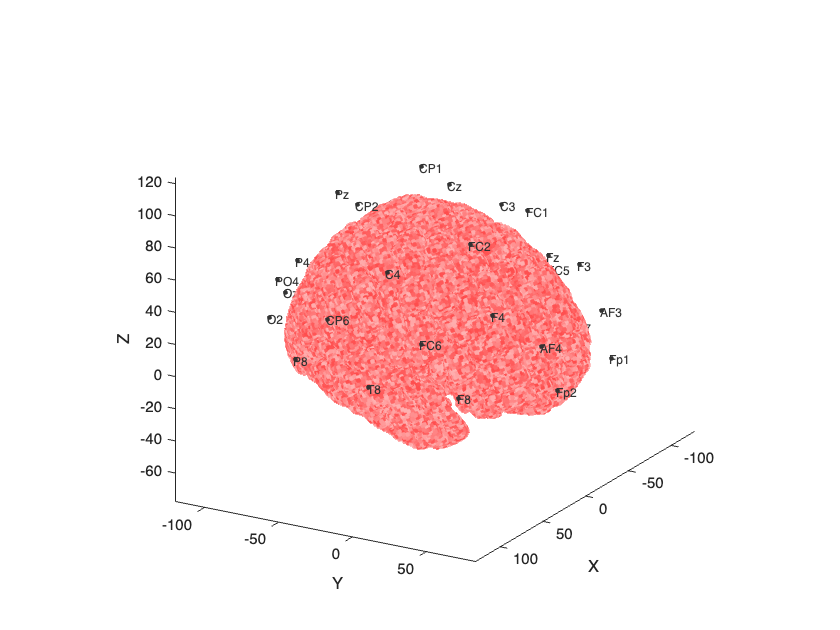

plot_headmodel(lf);

%plot_headmodel(lf, 'style', 'boundary', 'labels', 0);

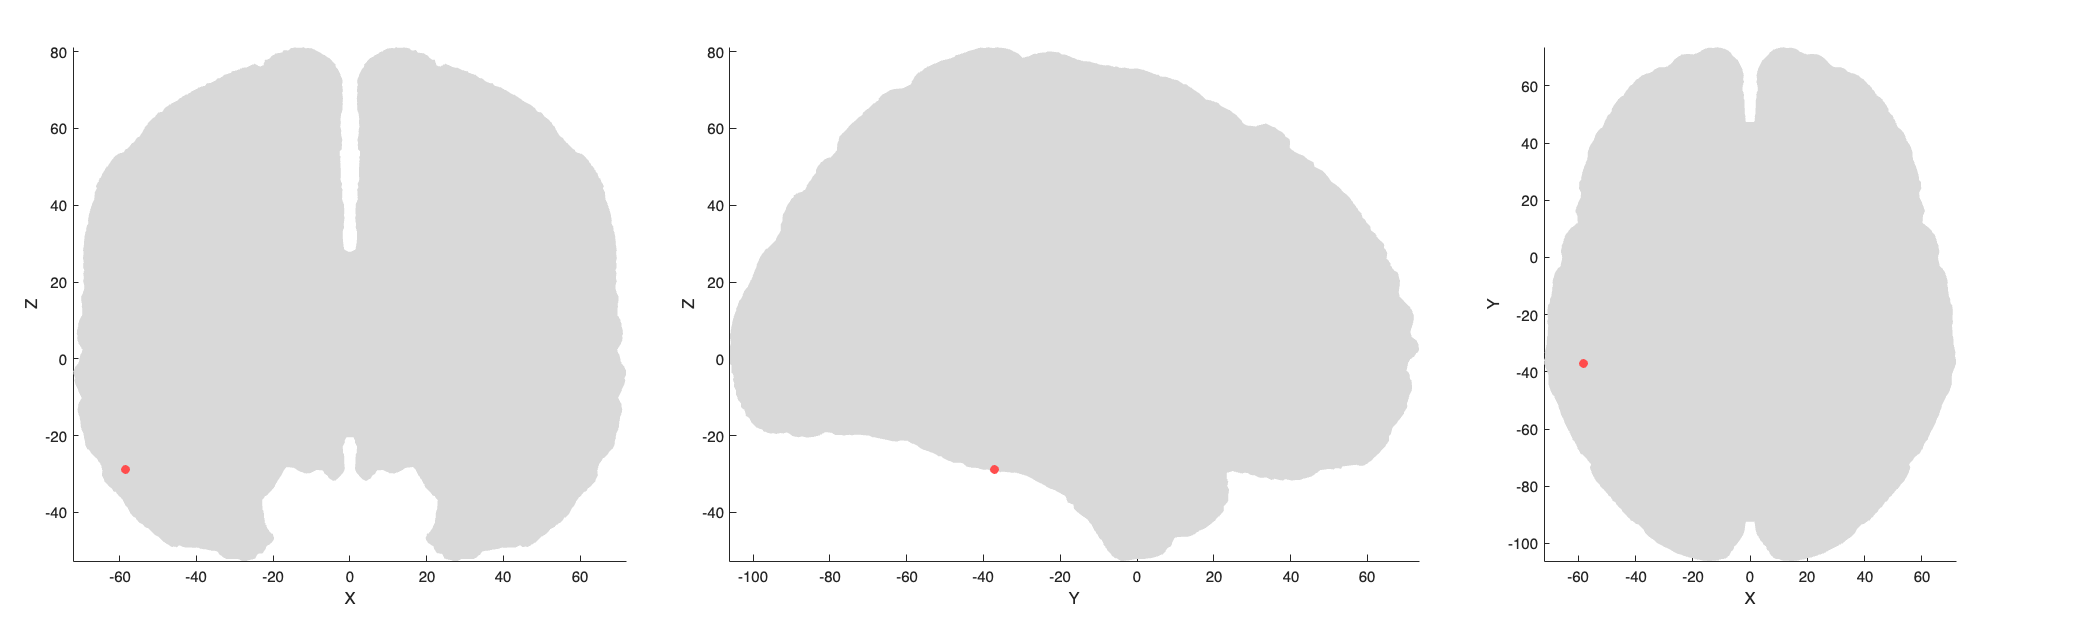

source = lf_get_source_random(lf);
plot_source_location(source, lf);

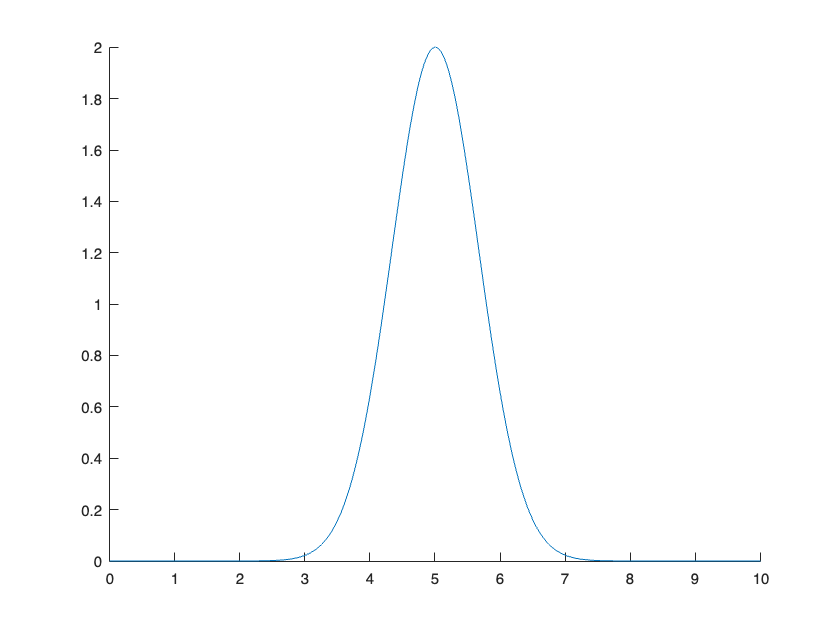

erp = struct();
erp.peakLatency = 5*1e03;      % in ms, starting at the start of the epoch
erp.peakWidth = 4*1e03;        % in ms
erp.peakAmplitude = 2;      % in microvolt
erp = utl_check_class(erp, 'type', 'erp'); 
plot_signal_fromclass(erp, epochs);

c = struct();
c.source = source;      % obtained from the lead field, as above
c.signal = {erp};       % ERP class, defined above

c = utl_check_component(c, lf);
%c.orientation = [0 1 0];
%c.orientation = utl_get_orientation_pseudoperpendicular(source, lf);
scalpdata = generate_scalpdata(c, lf, epochs);

Generating scalp data... 100.00%
      Remaining: 00:00:00
          Total: 00:00:01
Expected Finish: 2:50:37PM  13-Mar-2024                                                            


EEG = utl_create_eeglabdataset(scalpdata, epochs, lf);

Plotting...


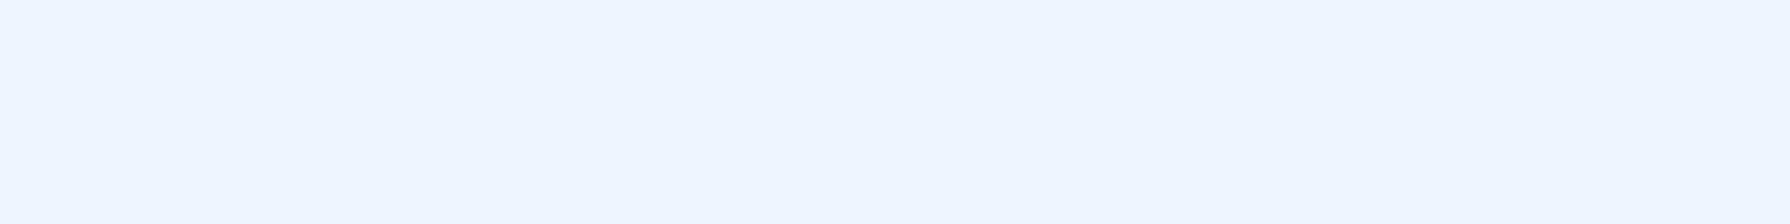

pop_topoplot(EEG, 1, [1000,2000, 3000, 4000, 5000, 6000, 7000, 8000], '', [1,8]);

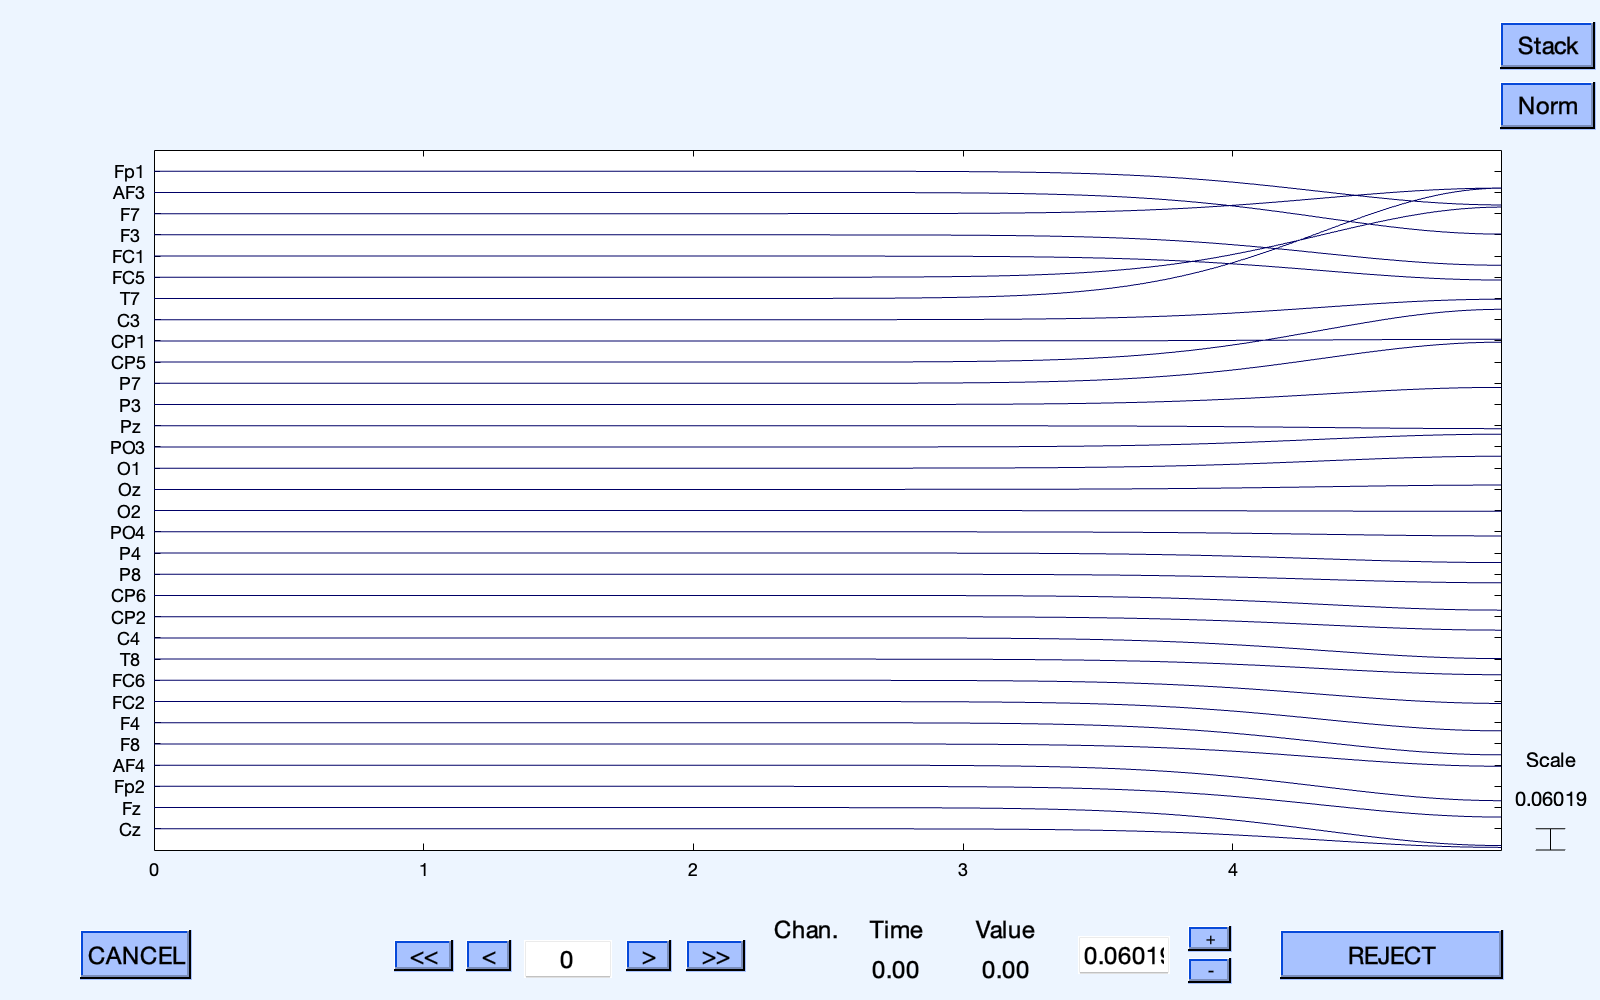

pop_eegplot(EEG, 1, 1, 1);

ans =   Figure (6: Noise signal) with properties:

      Number: 6
        Name: 'Noise signal'
       Color: [0.9400 0.9400 0.9400]
    Position: [440 378 560 420]
       Units: 'pixels'

  Show all properties


noise = struct( ...
        'type', 'noise', ...
        'color', 'white', ...
        'amplitude', 1);
noise = utl_check_class(noise);
plot_signal_fromclass(noise, epochs)

c = struct();
c.source = source;  
c.signal = {noise};
c = utl_check_component(c, lf);
%c.orientation = [0 1 0];
%c.orientation = utl_get_orientation_pseudoperpendicular(source, lf);
scalpdata = generate_scalpdata(c, lf, epochs);

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to the parallel pool (number of workers: 4).
Generating scalp data... 100.00%
      Remaining: 00:00:00
          Total: 00:00:03
Expected Finish: 2:17:53PM  13-Mar-2024                                                            


EEG = utl_create_eeglabdataset(scalpdata, epochs, lf);

Plotting...


pop_topoplot(EEG, 1, [1000,2000, 3000, 4000, 5000, 6000, 7000, 8000], '', [1,8]);

You are using a new version of eegplot - if you encounter problems
type "edit eegplot.m" and change FORCE_EEGPLOT_LEGACY to true


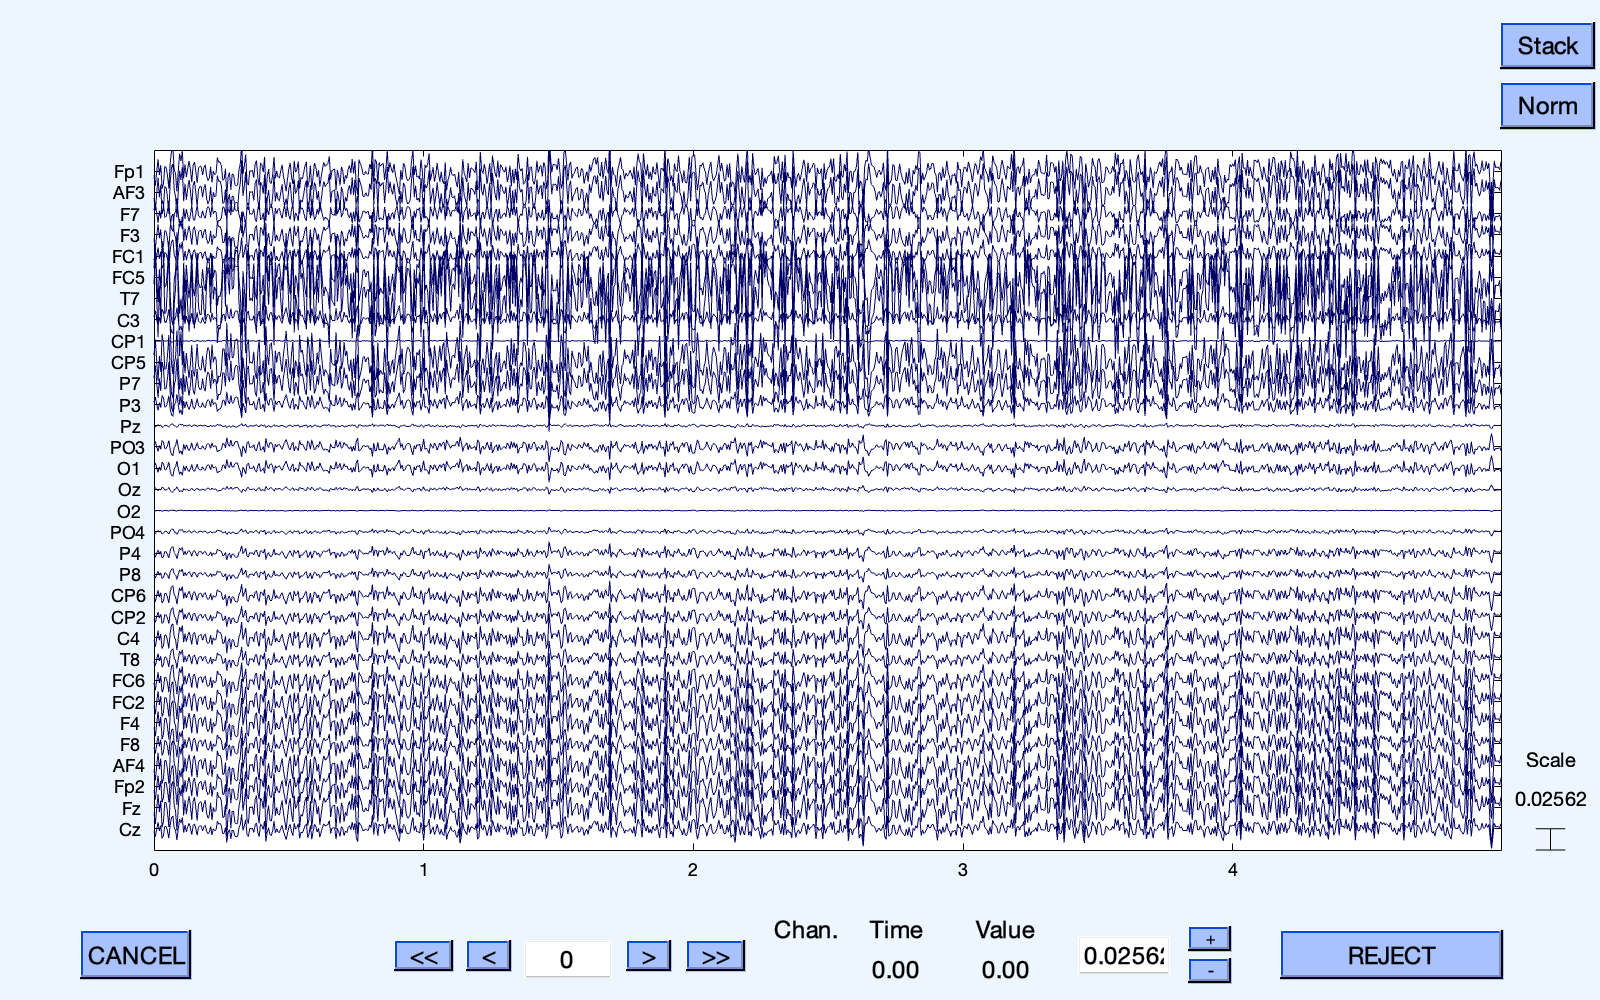

pop_eegplot(EEG, 1, 1, 1);

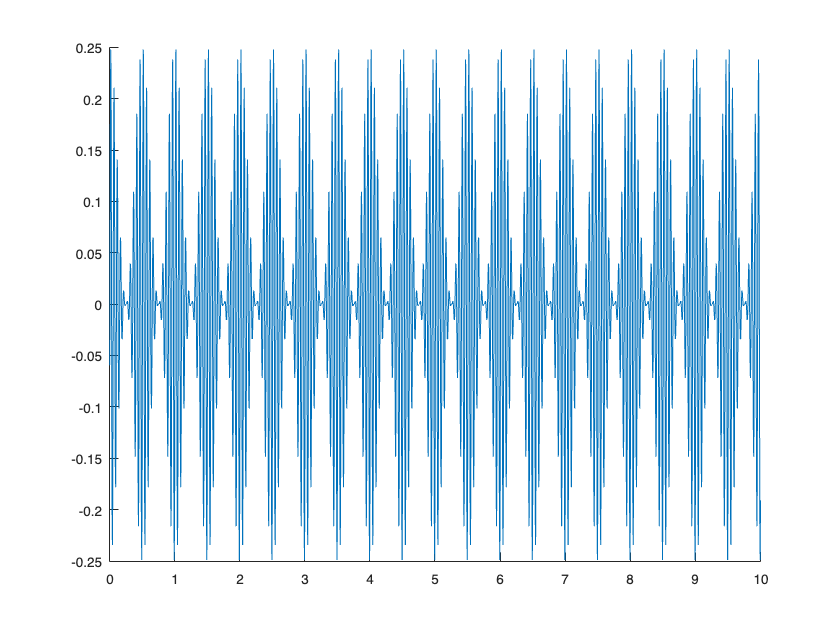

ersp = struct( ...
        'type', 'ersp', ...
        'frequency', [12 15 25 28], ...
        'amplitude', .25, ...
        'modulation', 'none');

ersp = utl_check_class(ersp);
ersp.frequency = 20;
ersp.modulation = 'ampmod';
ersp.modFrequency = 2;
ersp.modPhase = .25;

ersp = utl_check_class(ersp);

plot_signal_fromclass(ersp, epochs);

c = struct();
c.source = source;  
c.signal = {noise};
c = utl_check_component(c, lf);
%c.orientation = [0 1 0];
%c.orientation = utl_get_orientation_pseudoperpendicular(source, lf);
scalpdata = generate_scalpdata(c, lf, epochs);

Generating scalp data... 100.00%
      Remaining: 00:00:00
          Total: 00:00:01
Expected Finish: 2:35:57PM  13-Mar-2024                                                            


EEG = utl_create_eeglabdataset(scalpdata, epochs, lf);

Plotting...


pop_topoplot(EEG, 1, [1000,2000, 3000, 4000, 5000, 6000, 7000, 8000], '', [1,8]);

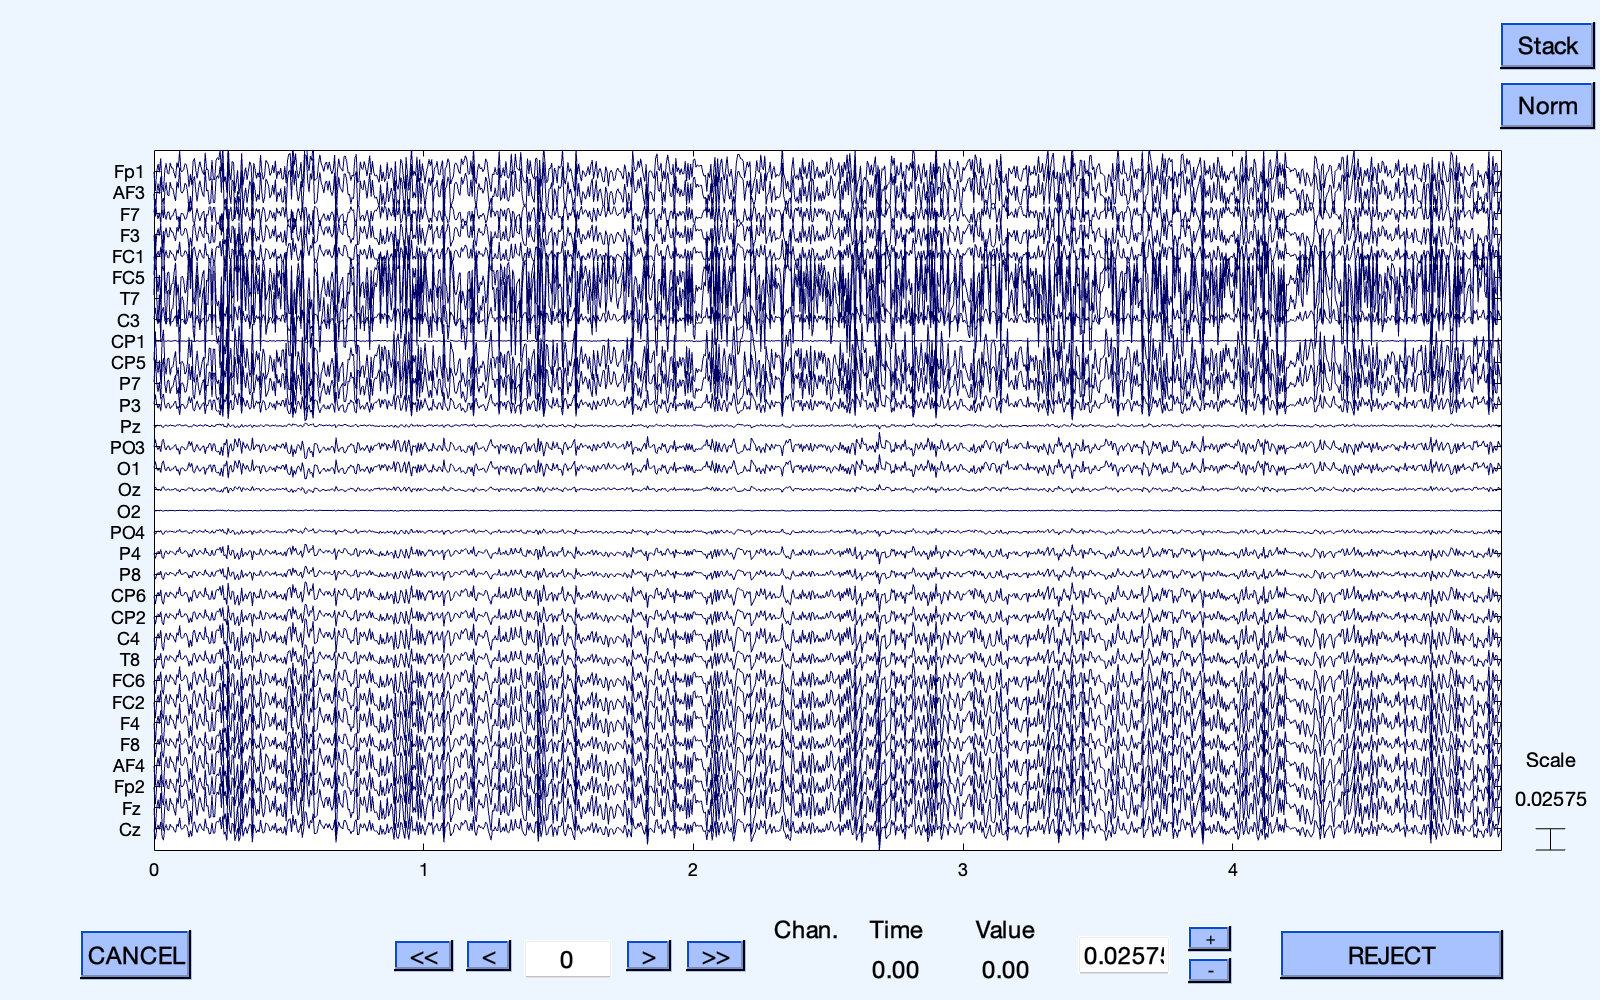

pop_eegplot(EEG, 1, 1, 1);

c.signal = {erp, ersp, noise};
EEG = utl_create_eeglabdataset(generate_scalpdata(c, lf, epochs), ...
        epochs, lf);

Generating scalp data... 100.00%
      Remaining: 00:00:00
          Total: 00:00:02
Expected Finish: 2:42:00PM  13-Mar-2024                                                            


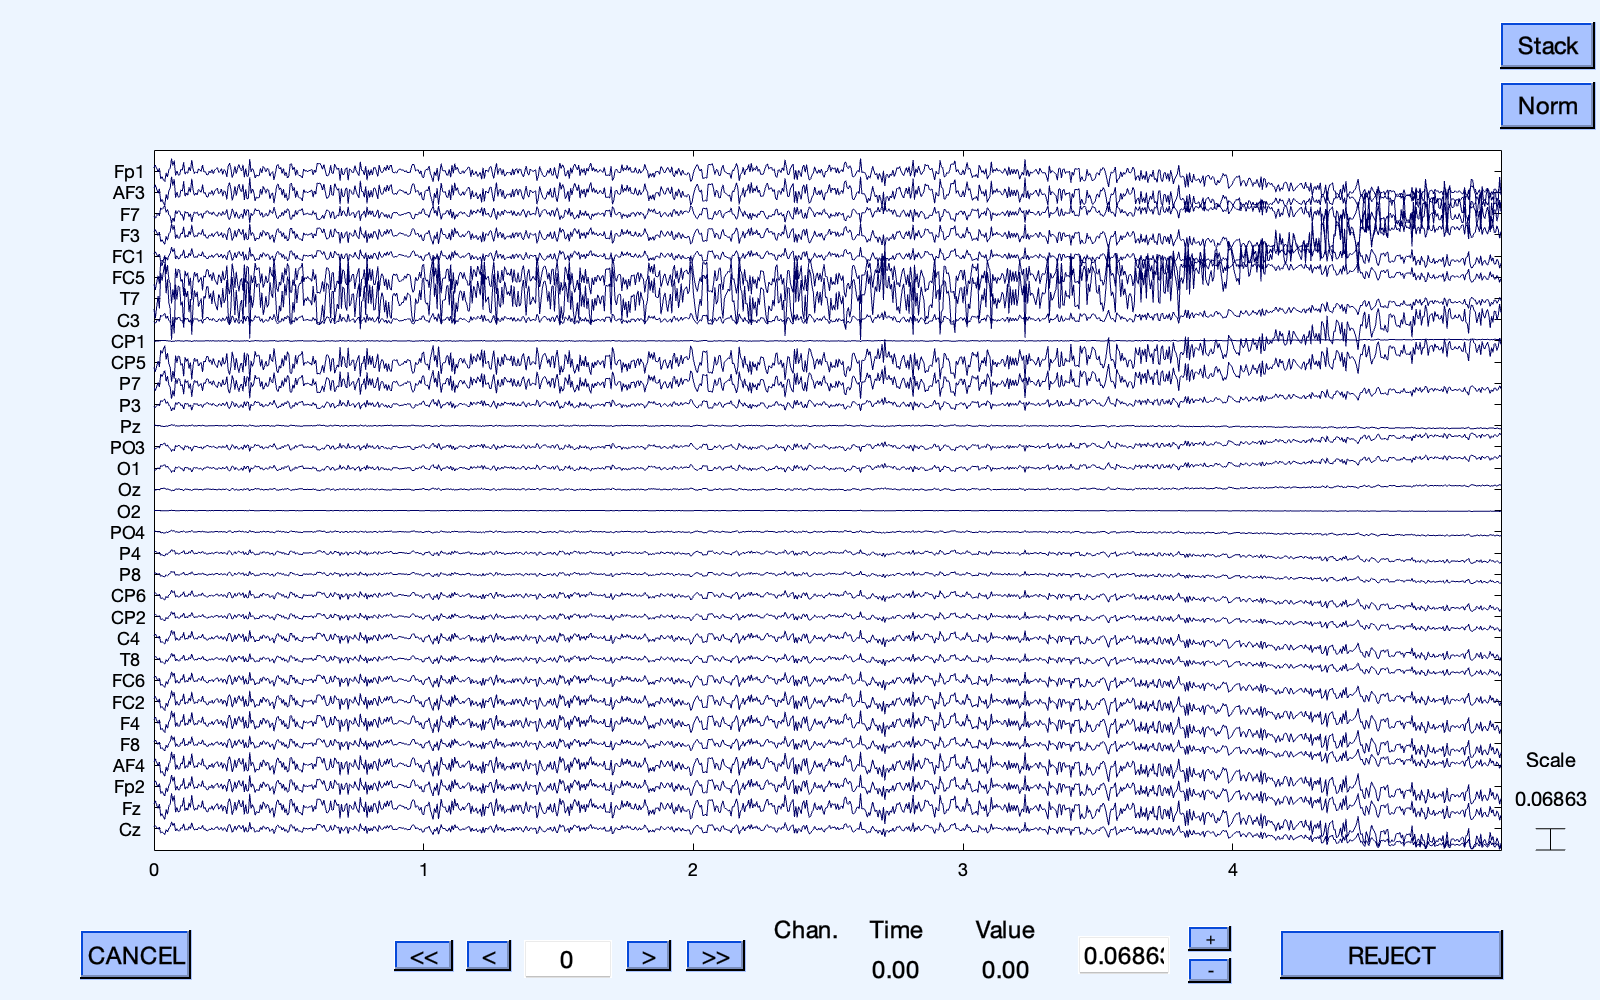

pop_eegplot(EEG, 1, 1, 1);

pop_topoplot(EEG, 1, [1000,2000, 3000, 4000, 5000, 6000, 7000, 8000], '', [1,8]);

Unrecognized function or variable 'EEG'.


sourcelocs  = lf_get_source_spaced(lf, 2, 150);

Unrecognized function or variable 'lf'.

plot_source_location(sourcelocs, lf);

sourcelocs  = lf_get_source_spaced(lf, 10, 50);

Unrecognized function or variable 'lf'.

%erp = erp_get_class_random([1:5], [5000:10000], [25:200], ...
%		[-1:.1:-.5, .5:.1:1], 'numClasses', 10);
erp = erp_get_class_random([5:10], [5000:10000], [50:100], ...
		[-0.4:0.1:-0.1, 0.65:0.1:1], 'numClasses', 10);



% combining into components
c = utl_create_component(sourcelocs, erp, lf);

% plotting each component's projection and activation
plot_component(c, epochs, lf);
erp1 = struct();
erp1.peakLatency = 5*1e03;      % in ms, starting at the start of the epoch
erp1.peakWidth = 4*1e03;        % in ms
erp1.peakAmplitude = 1;      % in microvolt
erp1 = utl_check_class(erp1, 'type', 'erp'); 
noise = struct( ...
        'type', 'noise', ...
        'color', 'white', ...
        'amplitude', 1);
%erp_new = [erp1, noise]
c1 = utl_create_component(sourcelocs(1), erp1, lf);
c3 = utl_create_component(sourcelocs(2), noise, lf);
c = [c1, c3];
plot_component(c, epochs, lf);

EEG = utl_create_eeglabdataset(generate_scalpdata(c, lf, epochs), ...
        epochs, lf);

Unrecognized function or variable 'c'.

pop_eegplot(EEG, 1, 1, 1);
pop_topoplot(EEG, 1, [1000,2000, 3000, 4000, 5000, 6000, 7000, 8000], '', [1,8]);

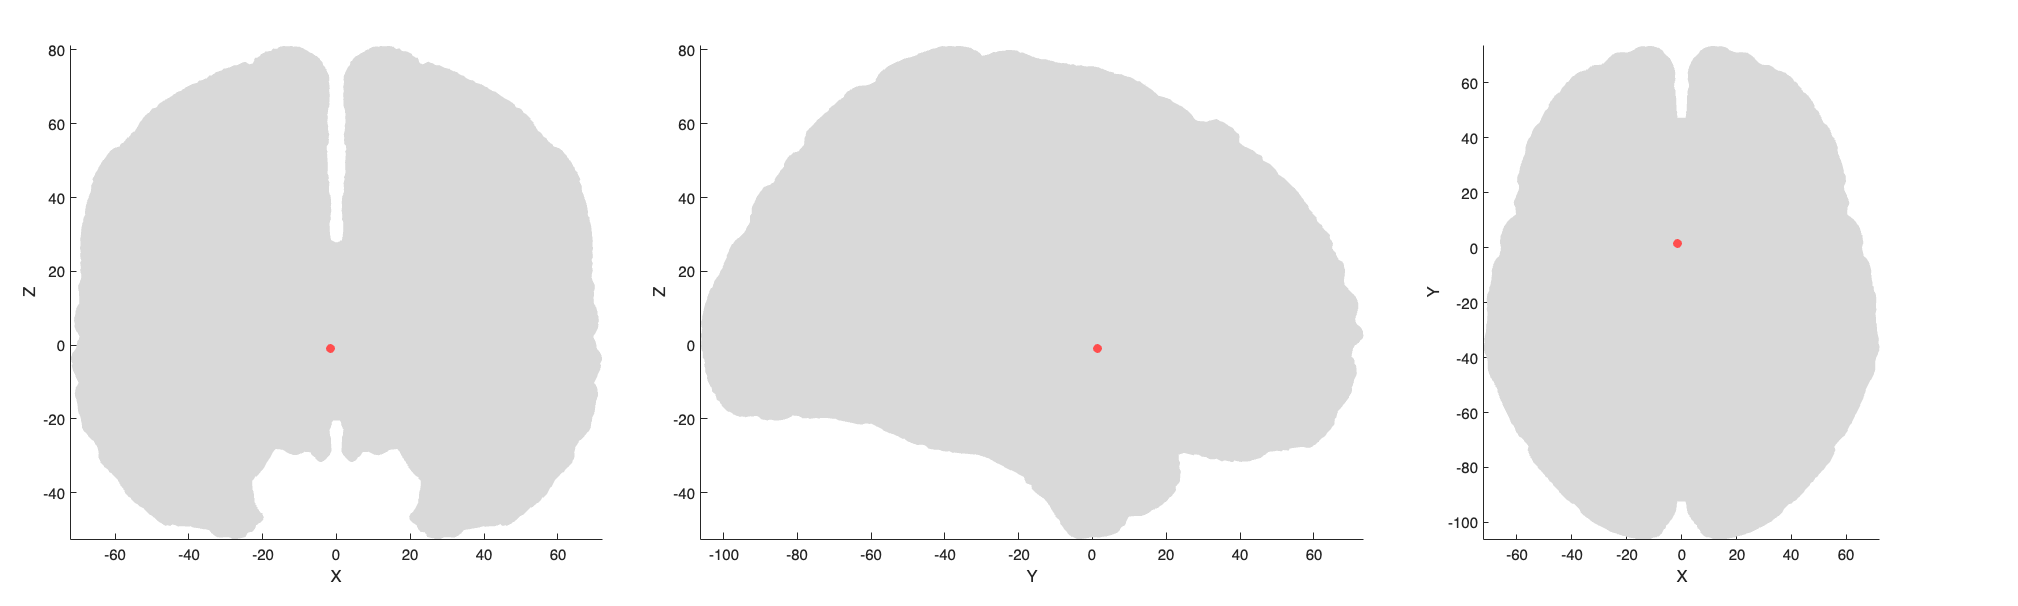

musc_source = lf_get_source_nearest(lf, [0 0 0]);
plot_source_location(musc_source, lf);

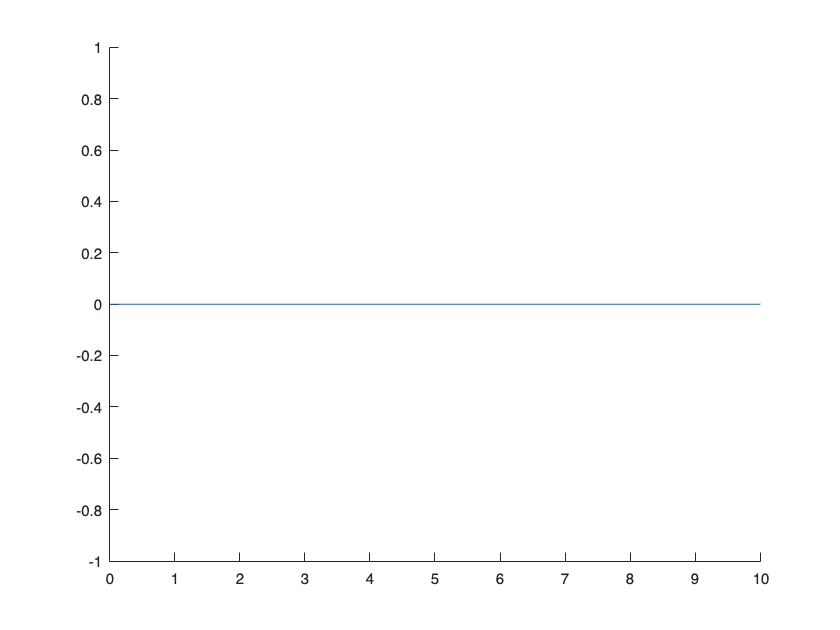

tot_len = 600; 
t_on = randi(600);
artlen = randi([30, tot_len-t_on]);
sig = get_musc_artifact(t_on, artlen);
plot_signal_fromclass(sig, epochs);


noise = struct( ...
                    'type', 'noise', ...
                    'color', 'white', ...
                     'amplitude', 0.8);
c3 =  struct();
c3.source = musc_source;
c3.signal = {noise,sig};
c3 = utl_check_component(c3, lf);

EEG = utl_create_eeglabdataset(generate_scalpdata(c, lf, epochs), ...
        epochs, lf);

Unrecognized function or variable 'c'.



pop_eegplot(EEG, 1, 1, 1);

pop_topoplot(EEG, 1, [1000,2000, 3000, 4000, 5000, 6000, 7000, 8000], '', [1,8]);